iexpt = 1;
path = 'D:\Documents\seam_cell_smFISH_data\Data\ceh-20\tiffs\L1_10_cell\Good_Q\';

spotVsThData = fun1(iexpt, path);

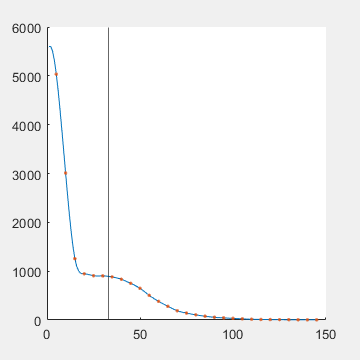

Error using ginputWhite (line 83)
Interrupted by figure deletion

Error in checkThreshold>fun2/plotFig1 (line 141)
            [~,~,but]=ginputWhite(1);

Error in 

fun2(iexpt, path, spotVsThData)

function spotVsThData = fun1(iexpt, path)


% load whole worm mask crops
load([path,'analyzed\',sprintf('filteredSpotData_#_%04d.mat', iexpt)], 'data_filtered', 'ROI_BB');

clear regmax;

% set-up a threshold gradient
Im  = max(data_filtered.im,[],3);
thresAll = 5:5:max(Im,[],'all');

spotVsThData = struct('threshold',{},'spotPos',{},'spotTotal',{});

for thresIdx = length(thresAll):-1:1
    
    % loop over rois on each stack
    for z=size(data_filtered.im,3):-1:1
        
        % skip slices with no ROIs
        if ~any(data_filtered.im(:,:,z),'all')
            continue
        end
        
        % image segmentation: only leave pixels above the threshold
        roiIm = double(data_filtered.im(:,:,z));
        roiMask = (roiIm > thresAll(thresIdx)) .* roiIm;
        
        % find regional maxima to seperate spots that touch
        % or leave as all 0 pixels
        if any(roiMask>0)
            regmax(:,:,z)=imregionalmax(roiMask);
        else
            regmax(:,:,z)=roiMask;
        end
        
    end
    
    % record all connected components from the regmax result (= spots)
    % coordinate = centroid of each spot
    spotIdx = bwlabeln(regmax);
    spotPos = regionprops(spotIdx,'Centroid');
    
    % save coordinates and number of spots
    % preallocate
    
    % save threshold
    spotVsThData(thresIdx).threshold = thresAll(thresIdx);
    
    % save spot [x,y] coordinates
    if ~isempty(spotPos)
        % struct 2 numeric array
        tmp = vertcat(spotPos.Centroid);
        % ROI to full image coordinates conversion
        tmp = [tmp(:,1:2) + ROI_BB(1:2) - 1, tmp(:,3)];
%         % integer / pixel accuracy
%         tmp = round(tmp);
%         % remove repeated rows
%         tmp = unique(tmp,"rows");
        spotVsThData(thresIdx).spotPos = tmp;
        
        % save total number of spots
        spotVsThData(thresIdx).spotTotal = length(spotPos);
        
    else
        spotVsThData(thresIdx).spotPos = [];
        spotVsThData(thresIdx).spotTotal = 0;
    end
    
end
end



function fun2(iexpt, path, spotVsThData)

global extension thresholds
rnaChn = 'Cy5';


% load ROI to get Z-stacks with ROI
load([path,'analyzed\',sprintf('ROI_#_%04d.mat', iexpt)], 'roi');
sliceAll = find(~cellfun('isempty',roi));

% load stacks with ROI selection
fileName=sprintf(['%s%03d', extension], rnaChn, iexpt);
imIn = tiffreadFast([path,fileName], sliceAll);

% initialise z
SS = get(0,'ScreenSize');

plotFig2
plotFig1

    function plotFig1
        % display from midstack and midthreshold
        z = length(sliceAll)/2;
        thIdx = round(length(spotVsThData)/5);
        
        hFig1 = figure('position', [(SS(3)-SS(4))/2, 0,  SS(4)-100, SS(4)-100],...
            "Visible","on");
        
        cont=true;
        while cont
            cla;
            
            % adjust contrast
            lowhigh = stretchlim(imIn(:,:,z), thresholds(3));
            Im = imadjust(imIn(:,:,z),lowhigh);
            
            % display image
            hIm = imshow(Im,'InitialMagnification','fit');
            
            title(sprintf('stack%d, Th = %d',sliceAll(z),spotVsThData(thIdx).threshold))
            
            % add scroll bar to control zoom
%             hSP = imscrollpanel(hFig1,hIm);
%             set(hSP,'Units','normalized','Position',[0, .1, 1, .9])
%             hMagBox = immagbox(hFig1,hIm);
%             magPos = get(hMagBox,'Position');
%             set(hMagBox,'Position',[0, 0, magPos(3), magPos(4)])
%             imoverview(hIm)
%             api = iptgetapi(hSP);
%             mag = api.getMagnification();
%             r = api.getVisibleImageRect();
%             api.setMagnificationAndCenter(1,1,500)
            
            hold on;
            
            iz = spotVsThData(thIdx).spotPos(:,3) == sliceAll(z);
            X = spotVsThData(thIdx).spotPos(iz,1);
            Y = spotVsThData(thIdx).spotPos(iz,2);
            plot (X,Y,'or')
            
            hold off;
            
            [~,~,but]=ginputWhite(1);
            
            % move stack
            if ismember(but,[113,101,119,114])
                switch but
                    case 113
                        z = z-1;
                    case 101
                        z = z-5;
                    case 119
                        z = z+1;
                    case 114
                        z = z+5;
                end
                if z<1
                    z=1;
                end
                if z>length(sliceAll)
                    z=length(sliceAll);
                end
                
                % move contrast
            elseif but == 91 || but == 93
                if but == 91
                    thIdx = thIdx - 1;
                else
                    thIdx = thIdx + 1;
                end
                if thIdx < 1
                    thIdx = 1;
                end
                if thIdx > length(spotVsThData)
                    thIdx = length(spotVsThData);
                end
                
                % 'ESC' - save and start next
            elseif but==27
                cont=false;
            end
            
        end
        close(gcf)
    end
%     end

    function plotFig2
        load([path,'analyzed\',sprintf('spotThresholds%04d.mat', iexpt)], 'spotThreshold');
        fig2 = figure('position', [(SS(3)+SS(4))/2, SS(4)/3,  SS(4)/3, SS(4)/3]);
        set(gcf,'Visible','on')
        X = [spotVsThData.threshold];
        Y = [spotVsThData.spotTotal];
        fitX = 1:1:max(X);
        fitY = interp1(X,Y,fitX,'spline');
        
        hold on
        plot (fitX,fitY,'-')
        plot (X,Y,'.')
        xline(spotThreshold)
        hold off
        
    end

end


